# Example 2: F-16

Clear the work environment and check dependencies.

clear; clc; close all;
% Check if user has Yalmip installed
has_yalmip = exist("yalmip",'file');
if(has_yalmip)
    yalmip('clear')
end
% Check for MPT3
assert(exist("Polyhedron","file"), ...
    "MPT3 toolbox is required.")

## Problem Description

### Enter Problem Data

Enter the problem data as a structure. Begin with the system description:

$\mathbf{x}^+ = A\mathbf{x} + B\mathbf{u} + E\mathbf{d}$,

$\mathcal{D} = \{\mathbf{d} \in \mathbb{R}^q \mid \|\mathbf{d}\|_{\infty} \leq d_{\infty}\}$.

***Note****: Other set descriptions for *$\mathcal{D}$ *are allowed as long as it is compact, but require further  source code changes.*

dt = 0.1;
A_ct = [0 1 0 0 0;
       0 -0.86939 43.223 -17.251 -1.5766 ;
       0 0.99335 -1.3411 -0.16897 -0.25183;
       0 0 0 -20 0;
       0 0 0 0 -20];
B_ct = [0 0; 0 0; 0 0; 20 0; 0 20];
[data.A,data.B] = c2d(A_ct,B_ct,dt);
data.E = [0 0 0; 0.0175 0 0; 0 0 0; 0 0.0524 0; 0 0 0.0524];
data.d_max = 1; % Noise bound
clear A_ct B_ct
data.n = size(data.A,1);
data.m = size(data.B,2);
% Check stabilizability
if(rank(ctrb(data.A, data.B)) ~= data.n)
  warning("Pair (A,B) is not controllable, " + ...
      "please verify it is stabilizable.")
end

Enter now state and input constraints

$\mathcal{X} = \{\mathbf{x} \in \mathbb{R}^n \mid  W\mathbf{x} \leq \mathbf{z}\}$,

$\mathcal{U} = \{\mathbf{u} \in \mathbb{R}^m \mid  M\mathbf{u} \leq \mathbf{b}\}$.

data.W = [zeros(3,2), eye(3); zeros(3,2), -eye(3)];
data.z = deg2rad([4;25;20;4;25;20]);
data.X = Polyhedron(data.W, data.z);
data.M = zeros(1,data.m);
data.b = 0;
data.U = Polyhedron(data.M,data.b);

Check if $\mathcal{X}$ and $\mathcal{U}$ are compact and issue warning if not.

if(isinf(data.X.volume)) % not compact data.X
  warning("The state constraint set $\mathcal{X}$ is not compact." + ...
      "The RMOAS may not be finitely determined.")
end

if(isinf(data.U.volume)) % not compact data.U
  warning("The input constraint set $\mathcal{U}$ is not compact.")
end

Design the tracking output that will track the desired reference $\mathbf{r} \in \mathbb{R}^m$

$\mathbf{y}_r = C_r \mathbf{x} + D_r \mathbf{u}$.

data.C_r = [1 0 0 0 0; 1 0 -1 0 0];
data.D_r = zeros(2);
assert(size(data.C_r,1) == data.m)
assert(size(data.C_r,2) == data.n)
assert(size(data.D_r,1) == data.m)
assert(size(data.D_r,2) == data.m)

Obtain the steady-state manifold basis $G_x$ and $G_u$.

[data.G_x, data.G_u] = moas_ss_basis(data.A, data.B, data.C_r, data.D_r);

### Controller Design

Let us design the prestabilizing $\pi$ and nominal $\kappa$ controllers.

data.Q = diag([10,0,10,0,0]);
data.R = 1e-3*diag([1,1]);
data.K_kappa = dlqr(data.A,data.B,data.Q,data.R);
data.kappa = @(x,r) data.G_u*r - data.K_kappa*(x - data.G_x*r); % Nominal
data.K_pi = dlqr(data.A,data.B,data.Q, 10*data.R);
data.pi = @(x,r) data.G_u*r - data.K_pi*(x - data.G_x*r); % Pre-stabilizing

### Compute the RMOAS

The functions below compute $\mathcal{O}_{\infty}^{\epsilon}$ and $\mathbf{\phi}_k$.

data.epsilon = 0.15;
data.eta = 0.1;
[data.H_rmoas, data.c_rmoas, data.phi_rmoas] = rmoas_oinf(data, data.K_pi);
data.RMOAS = Polyhedron(data.H_rmoas,data.c_rmoas);
data.PRMOAS = data.RMOAS.projection(1:size(data.A,1)); % projection

## Simulate Response

### Enter Simulation Parameters

Enter now parameters such as the simulation horizon, initial conditions $\mathbf{x}_0$ and desired reference $\mathbf{r}$

N = 20; % Simulation horizon
r = deg2rad([9;6.5]); % Desired reference
x0 = deg2rad([0;0;0;0;0]); % Initial state
assert(length(x0) == data.n);
assert(length(r) == data.m);

### Setup the RDCBF-QP

Let us prepare the data for the RDCBF-QP optimization problem


$$\min_{u\in\mathcal{U}} \quad \|\mathbf{u} - \kappa(\mathbf{x},\mathbf{r})\|^2 + \eta\|\mathbf{\rho} - \mathbf{r}\|^2\\
\text{s.t.} \quad ~~ (\mathbf{u},\mathbf{\rho}) \in \mathcal{K}(\mathbf{x},\mathbf{v})$$


data.M_K = data.H_rmoas*[data.B, zeros(data.n,data.m); zeros(data.m,data.m), eye(data.m)];
data.b_K = @(x) data.c_rmoas - data.phi_rmoas - data.H_rmoas*[data.A; zeros(data.m,data.n)]*x;
if(has_yalmip)
  rdcbf = rdcbf_compile(data);
else
  [H_qp, f_qp, A_qp, b_qp] = rdcbf_quadprog(data);
  rdcbf = @(x,r) quadprog(H_qp, f_qp(x,r), A_qp, b_qp(x));
end

% rdcbf(x,r) yields the solution to RDCBF-QP at x and r.

### Simulate

Let us simulate the disturbed RDCBF-filtered closed-loop system

$\mathbf{x}_{k+1} = A\mathbf{x}_k + B\beta(\mathbf{x}_k) + E\mathbf{d}_k$.

% Initialize history variables
x = zeros(data.n,N+1);
u = zeros(data.m,N);
x(:,1) = x0;
st = zeros(N,1); % Solvetimes

% Simulate
for k = 1:N
  d = data.d_max*(2*rand(size(data.E,2),1) - 1);
  % Solve and check for errors
  if (has_yalmip)
    [u(:,k), errorcode, st(k)] = rdcbf(x(:,k),r);
    assert(~errorcode,strcat("RDCBF-QP solver failed: ",num2str(errorcode)));
  else
    tic
    [u(:,k), ~, errorcode] = rdcbf(x(:,k),r);
    st(k) = toc;
    assert(errorcode==1,strcat("RDCBF-QP solver failed: ",num2str(errorcode)));
  end
  x(:,k+1) = data.A*x(:,k) + data.B*u(:,k) + data.E*d;
end

## Plot Response and Display Performance Stats

### State and input response plot

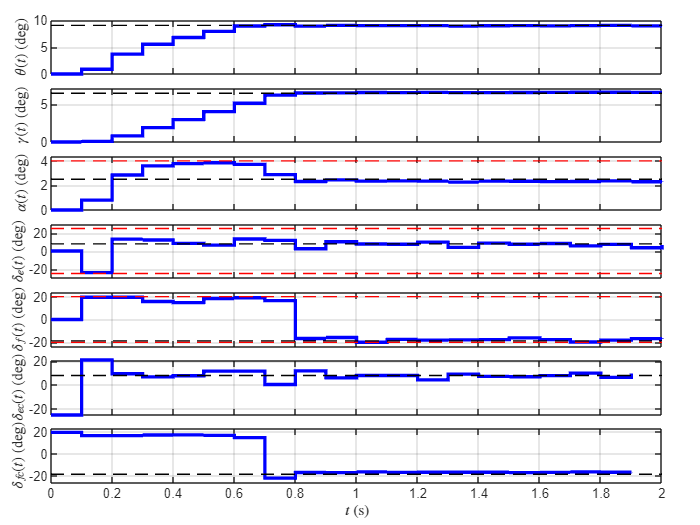

t = dt*(0:N)';
x_r = data.G_x*r;
u_r = data.G_u*r;
% 7-plot
figure(1)
tiledlayout(7,1,'Padding', 'compact', 'TileSpacing', 'tight')
nexttile(1)
stairs(t,rad2deg(x(1,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([x_r(1),x_r(1)]),'--k')
grid on
ylh_1 = ylabel("$\theta(t)$ (deg)",'Interpreter','latex');
set(gca,'xticklabel',[])

nexttile(2)
stairs(t,rad2deg(x(1,:) - x(3,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([r(2),r(2)]),'--k')
grid on
ylh_2 = ylabel("$\gamma(t)$ (deg)",'Interpreter','latex');
ylim([0,7.2]);
set(gca,'xticklabel',[])

nexttile(3)
stairs(t,rad2deg(x(3,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([x_r(3),x_r(3)]),'--k')
plot([t(1),t(end)],rad2deg([data.z(1),data.z(1)]),'--r')
plot([t(1),t(end)],-rad2deg([data.z(1),data.z(1)]),'--r')
grid on
ylh_3 = ylabel("$\alpha(t)$ (deg)",'Interpreter','latex');
ylim([0,4.4]);
set(gca,'xticklabel',[])

nexttile(4)
stairs(t,rad2deg(x(4,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([x_r(4),x_r(4)]),'--k')
plot([t(1),t(end)],rad2deg([data.z(2),data.z(2)]),'--r')
plot([t(1),t(end)],-rad2deg([data.z(2),data.z(2)]),'--r')
grid on
ylabel("$\delta_e(t)$ (deg)",'Interpreter','latex')
ylim(1.2*ylim)
set(gca,'xticklabel',[])

nexttile(5)
stairs(t,rad2deg(x(5,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([x_r(5),x_r(5)]),'--k')
plot([t(1),t(end)],rad2deg([data.z(3),data.z(3)]),'--r')
plot([t(1),t(end)],-rad2deg([data.z(3),data.z(3)]),'--r')
grid on
ylabel("$\delta_f(t)$ (deg)",'Interpreter','latex')
ylim(1.2*ylim)
set(gca,'xticklabel',[])

nexttile(6)
stairs(t(1:end-1),rad2deg(u(1,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([u_r(1),u_r(1)]),'--k')
grid on
ylabel("$\delta_{ec}(t)$ (deg)",'Interpreter','latex')
set(gca,'xticklabel',[])

nexttile(7)
stairs(t(1:end-1),rad2deg(u(2,:)),'b','LineWidth',2)
hold on
plot([t(1),t(end)],rad2deg([u_r(2),u_r(2)]),'--k')
grid on
ylh_7 = ylabel("$\delta_{fc}(t)$ (deg)",'Interpreter','latex');
xlabel("$t$ (s)", "Interpreter","latex")
ylim(1.2*ylim)

% Fix ylabel positions
ylh_1.Position(1) = ylh_7.Position(1);
ylh_2.Position(1) = ylh_7.Position(1);
ylh_3.Position(1) = ylh_7.Position(1);

### Solvetime performance

disp(strcat("Average solvetime [ms]: ", num2str(1000*mean(st))))

Average solvetime [ms]: 1.2842


disp(strcat("Maximum solvetime [ms]: ", num2str(1000*max(st))))

Maximum solvetime [ms]: 1.6193
